Re_act = 1

ans = 1.8500

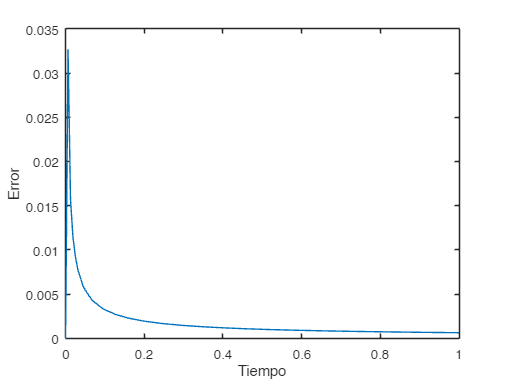

Re_act = 50

ans = 1.0838

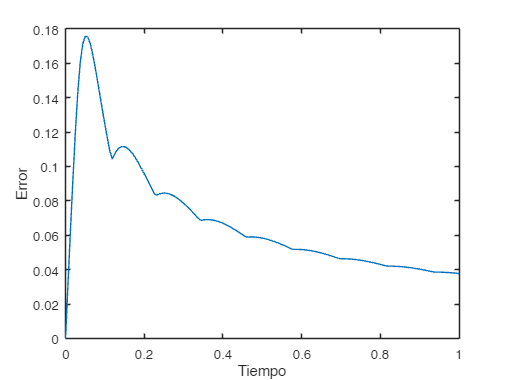

Re_act = 1000

ans = 1.0766

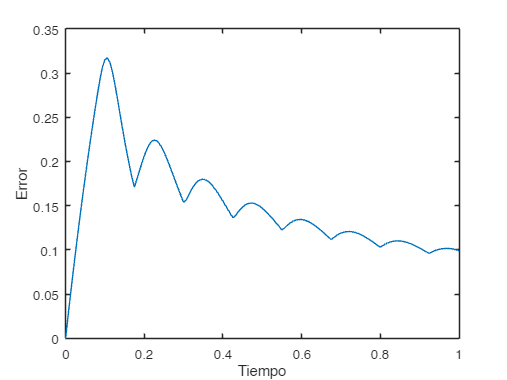


% --- Parámetros Generales ---
a = -10; b = 10;
T_final = 1.0;
Tol = 1e-15;
MaxIter = 500;
% Fijamos una malla fina que sepamos que funciona bien
Nx_fijo = 160;
Nt_fijo = 160;
Re_values = [1, 50, 1000];

Resultados_Re = [];
Solutions_Store = {};

for i = 1:3

    figure('Color','w');
    hold on;
    box on;
    Re_act = Re_values(i)
    [x_nodes, t_nodes, U_num, viter, ~] = CrankNicolson_trabajo(...
        @(t) -1, @(t) 1, 'funcionci', a, b, Nx_fijo, T_final, Nt_fijo, (1/Re_act), Tol, MaxIter);

    % Solución Exacta
    [T, X] = meshgrid(t_nodes, x_nodes);
    U_exact = ExactaBurgers(X, T, Re_act, a, b, 'funcionci');

    % Cálculo de Errores
    Error = abs(U_num - U_exact);
    plot(t_nodes, max(Error))
    xlabel('Tiempo')
    ylabel('Error')
    hold off;
end